# Tracking Plane speed and position Example

clearvars

**System Porperties**

dt = 1.0; %[sec] prediction time step
a = 2.0; %[m/s2] expected target acceleration

dPx = 20; %[m] expected position Process Error
dPv = 5; %[m/s] expected velocity Process Error

dx = 25; %[m] expected measuring accuracy
dv = 6; %[m/s] expected measuring accuracy


**Initial State**

v0 = 280; %Initial Speed
x0 = 4000; %initial position

**Measurments**

yM = [x0 v0;...
    4260 282;...
    4550 285;...
    4860 286;...
    5110 290;];

## Setup Problem

### **System Dynamics**


$$x_k = x_{k-1} + v_{k-1}\cdot \Delta t + a\cdot \frac{1}{2} \Delta t ^2$$


$\dot x = A\cdot x + B\cdot u +w_{noise} \\
y = H\cdot x + D\cdot u + z_{noise}$ @ $x \equiv \pmatrix{x \cr v}$


$$A = \pmatrix{1 & \Delta t \cr 0 & 1 }, \quad B = \pmatrix{\frac{1}{2}\Delta t^2 \cr \Delta t }$$


A = [1 dt; 0 1];
B = [0.5*dt^2; dt];


$$P \equiv \pmatrix{\Delta P x\cdot\Delta Px & \Delta Px\cdot\Delta Pv \cr \Delta Pv\cdot\Delta Px & \Delta Pv\cdot\Delta Pv } \approx \pmatrix{\Delta {Px}^2 & 0 \cr 0 & \Delta {Pv}^2}$$


P0 = [dPx^2 0; 0 dPv^2]; %Initial state Covariance matrix

### **Full State Measure**


$$y = H\cdot \pmatrix {x \cr v}$$



$$R \equiv \pmatrix{\Delta x\cdot\Delta x & \Delta x\cdot\Delta v \cr \Delta v\cdot\Delta x & \Delta v\cdot\Delta v } \approx \pmatrix{\Delta x^2 & 0 \cr 0 & \Delta v^2}$$


C = eye(2);
H = eye(2);
R = diag([dx^2, dv^2]);
I = eye(2);

## Setup Solution Functions

### Prediction Stage

X_k = cell(length(yM),1);
P_k = cell(length(yM),1);
X_kp = cell(length(yM),1);
P_kp = cell(length(yM),1);
KG = cell(length(yM),1);

X_kp_fun = @(i, X_k) A*X_k{i-1} + B*a;
P_kp_fun = @(i, P_k) A*P_k{i-1}*A';

### Update Stage

KG_fun = @(i, P_kp) P_kp{i}*H'*pinv(H*P_kp{i}*H'+R);
X_k_fun = @(i, X_kp, KG) X_kp{i} + KG{i}*(C*yM(i,:)' - H*X_kp{i});
P_k_fun = @(i, KG, P_kp) (I - KG{i}*H)*P_kp{i};

## Solution

### Initialization

X_k{1} = C*yM(1,:)';
X_kp{1} = X_k{1};
P_k{1} = P0;

### Iterating

for k = 2:length(yM)
    X_kp{k} = X_kp_fun(k, X_k);
    P_kp{k} = P_kp_fun(k, P_k);
    KG{k} = KG_fun(k, P_kp);
    X_k{k} = X_k_fun(k, X_kp, KG);
    P_k{k} = P_k_fun(k, KG, P_kp);
end

## Plotting

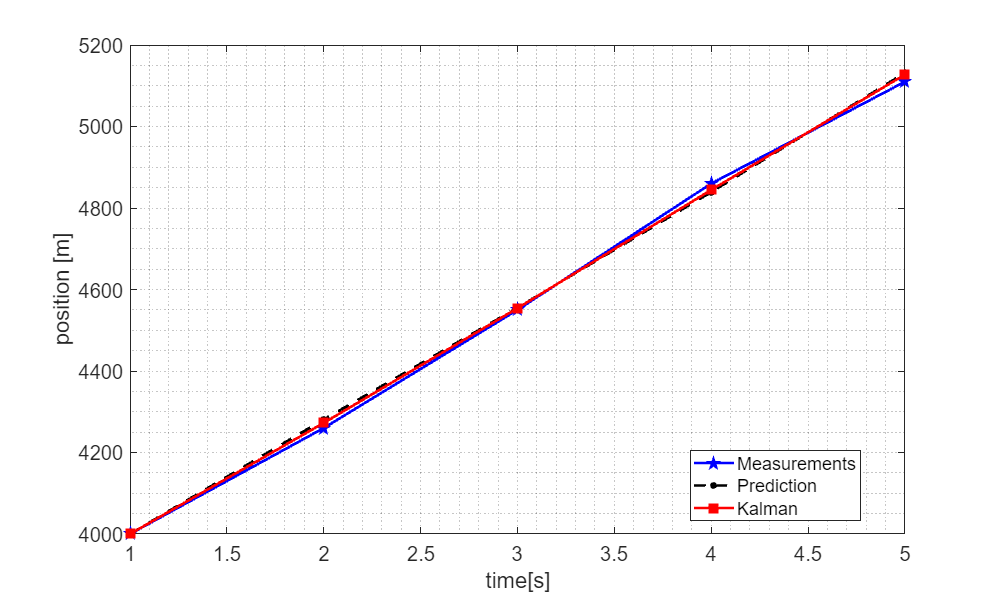

for i = 1:length(yM)
    state = X_k{i};
    statep = X_kp{i};
    
    xk(i) = state(1);
    vk(i) = state(2);

    xp(i) = statep(1);
    vp(i) = statep(2);
end

t = 1:length(yM);

figure('Name','Kalman Filter', 'Position', [0 0 1000 600])
plot(yM(:,1),'b-p', 'DisplayName','Measurements', LineWidth=2);
% text(t, yM(:,1)-10, num2str(yM(:,1)), 'Color','b')
hold on
plot(xp,'k--.', 'DisplayName','Prediction', 'MarkerSize',15, LineWidth=2);
% text(t, xp(:)-10, num2str(round(xp(:))), 'Color','k')
plot(xk,'r-s', 'DisplayName','Kalman','MarkerSize',8, 'MarkerFaceColor','r', LineWidth=2);
% text(t+0.1, xk(:)-10, num2str(round(xk(:))), 'Color','r')
legend('Location','best')
grid minor
xlabel ('time[s]')
ylabel('position [m]')
set(gca, 'Fontsize', 15)